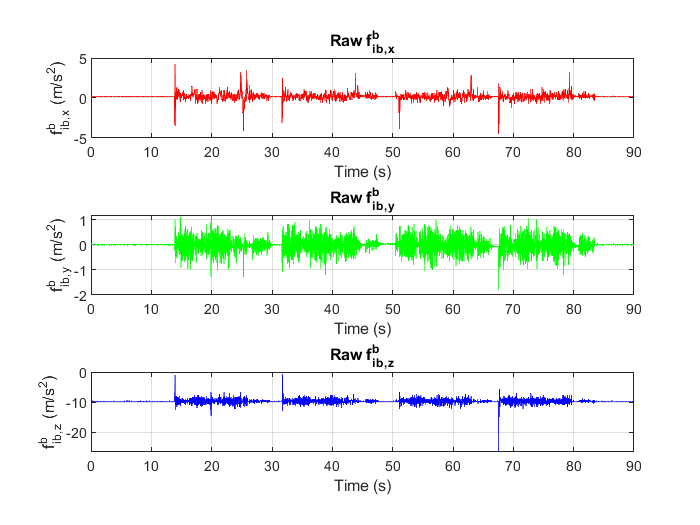

% Get IMU Rotated and Calibrated Correctly

% t = 0 : P.dt : P.init_time;
t = 0 : P.dt : P.t_end;

f_b__i_b_raw = P.accel(1:length(t), :);
w_b__i_b_raw = P.gyro(1:length(t), :);

%% Plot Accel Data_____________________________________________________
figure
subplot(3,1,1)
plot(t, f_b__i_b_raw(:,1), 'r')
title('Raw f^b_i_b_,_x')
xlabel('Time (s)')
xlim([0 t(end)])
ylabel('f^b_i_b_,_x (m/s^2)')
grid on
subplot(3,1,2)
plot(t, f_b__i_b_raw(:,2), 'g')
title('Raw f^b_i_b_,_y')
xlabel('Time (s)')
xlim([0 t(end)])
ylabel('f^b_i_b_,_y (m/s^2)')
grid on
subplot(3,1,3)
plot(t, f_b__i_b_raw(:,3), 'b')
title('Raw f^b_i_b_,_z')
xlabel('Time (s)')
xlim([0 t(end)])
ylabel('f^b_i_b_,_z (m/s^2)')
grid on

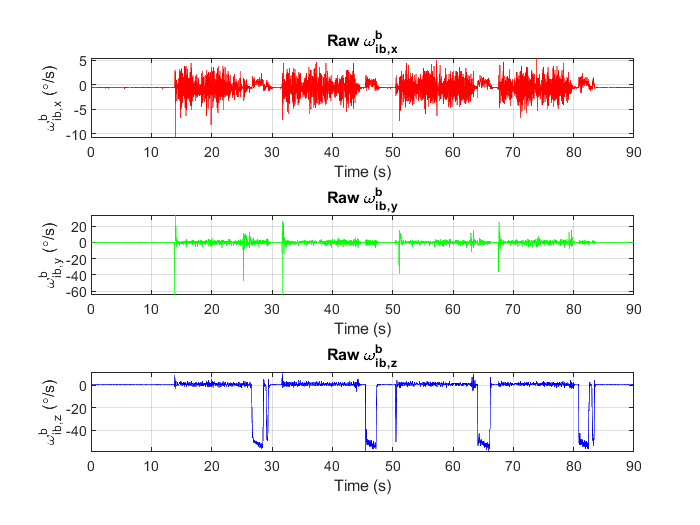


%% Plot Gyro Data______________________________________________________
figure
subplot(3,1,1)
plot(t, w_b__i_b_raw(:,1) * 180/pi, 'r')
title('Raw \omega^b_i_b_,_x')
xlabel('Time (s)')
xlim([0 t(end)])
ylabel('\omega^b_i_b_,_x (\circ/s)')
grid on
subplot(3,1,2)
plot(t, w_b__i_b_raw(:,2) * 180/pi, 'g')
title('Raw \omega^b_i_b_,_y')
xlabel('Time (s)')
xlim([0 t(end)])
ylabel('\omega^b_i_b_,_y (\circ/s)')
grid on
subplot(3,1,3)
plot(t, w_b__i_b_raw(:,3) * 180/pi, 'b')
title('Raw \omega^b_i_b_,_z')
xlabel('Time (s)')
xlim([0 t(end)])
ylabel('\omega^b_i_b_,_z (\circ/s)')
grid on

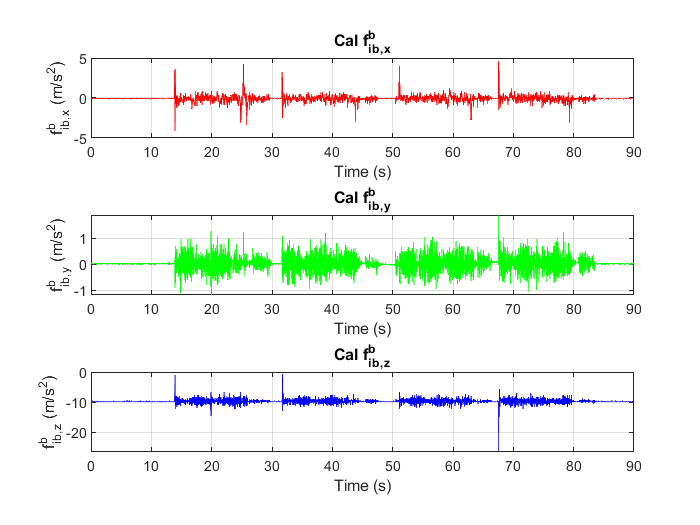

% Remove Fixed Bias and Misalignment

% Remove Fixed Bias and Misalignment for Accel
for k = 1 : length(t)
    f_b__i_b_cal(:,k) = P.C_b__imu * f_b__i_b_raw(k,:)';
end

% Remove Fixed Bias and Misalignment for Gyro
for k = 1 : length(t)
    w_b__i_b_cal(:,k) = P.C_b__imu * w_b__i_b_raw(k,:)';
end

%% Plot Accel Data_____________________________________________________
figure
subplot(3,1,1)
plot(t, f_b__i_b_cal(1,:), 'r')
title('Cal f^b_i_b_,_x')
xlabel('Time (s)')
xlim([0 t(end)])
ylabel('f^b_i_b_,_x (m/s^2)')
grid on
subplot(3,1,2)
plot(t, f_b__i_b_cal(2,:), 'g')
title('Cal f^b_i_b_,_y')
xlabel('Time (s)')
xlim([0 t(end)])
ylabel('f^b_i_b_,_y (m/s^2)')
grid on
subplot(3,1,3)
plot(t, f_b__i_b_cal(3,:), 'b')
title('Cal f^b_i_b_,_z')
xlabel('Time (s)')
xlim([0 t(end)])
ylabel('f^b_i_b_,_z (m/s^2)')
grid on

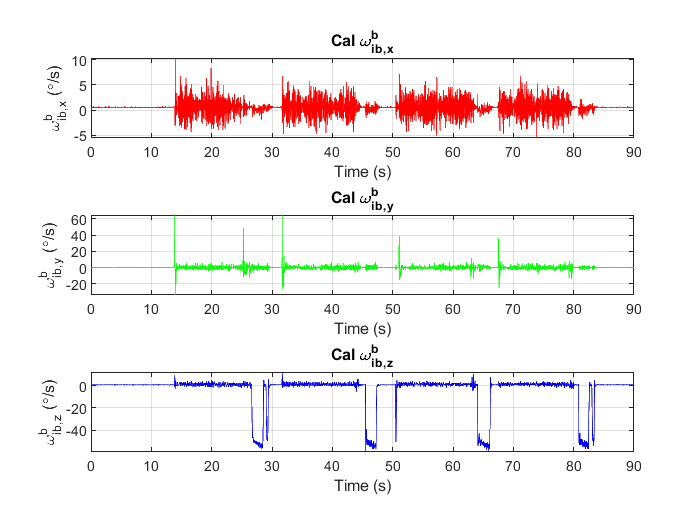


%% Plot Gyro Data______________________________________________________
figure
subplot(3,1,1)
plot(t, w_b__i_b_cal(1,:) * 180/pi, 'r')
title('Cal \omega^b_i_b_,_x')
xlabel('Time (s)')
xlim([0 t(end)])
ylabel('\omega^b_i_b_,_x (\circ/s)')
grid on
subplot(3,1,2)
plot(t, w_b__i_b_cal(2,:) * 180/pi, 'g')
title('Cal \omega^b_i_b_,_y')
xlabel('Time (s)')
xlim([0 t(end)])
ylabel('\omega^b_i_b_,_y (\circ/s)')
grid on
subplot(3,1,3)
plot(t, w_b__i_b_cal(3,:) * 180/pi, 'b')
title('Cal \omega^b_i_b_,_z')
xlabel('Time (s)')
xlim([0 t(end)])
ylabel('\omega^b_i_b_,_z (\circ/s)')
grid on